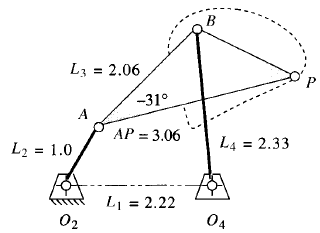

clear all
close all
clc

theta2 = sym('theta_2')

$$theta2 = \theta_{2}$$

theta3 = sym('theta_3')

$$theta3 = \theta_{3}$$

theta4 = sym('theta_4')

$$theta4 = \theta_{4}$$

l1=2.22; l2=1; l3=2.06; l4=2.33; AP = 3.06;
O2x=0; O2y=0;
O4x=l1; O4y=0;

### Equation of Motions

Ax = l2*cos(theta2);
Ay = l2*sin(theta2);
Bx = O4x-l4*cos(theta4);
By = O4y+l4*sin(theta4);

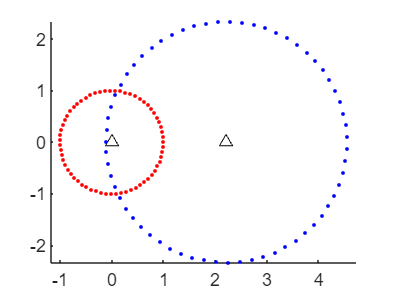

figure()
hold on
plot(O2x,O2y,"^k")
plot(O4x,O4y,"^k")
plot(subs(Ax,0:0.1:2*pi),subs(Ay,0:0.1:2*pi),".r")
plot(subs(Bx,0:0.1:2*pi),subs(By,0:0.1:2*pi),".b")
hold off
axis equal

eq1 = Bx == Ax+l3*cos(theta3);
eq2 = By == Ay+l3*sin(theta3);

sol = solve([eq1 eq2],[theta3 theta4]);

theta3_sol = sol.theta_3(1);
theta4_sol = sol.theta_4(1);

Px = Ax+AP*cos(theta3_sol-deg2rad(31)); Py = Ay+AP*sin(theta3_sol-deg2rad(31));

symvar([Ax Ay])

$$ans = \theta_{2}$$

symvar([Bx By])

$$ans = \theta_{4}$$

symvar([Px Py])

$$ans = \theta_{2}$$

BxNew = subs(Bx,theta4,theta4_sol);
ByNew = subs(By,theta4,theta4_sol);
symvar([BxNew ByNew])

$$ans = \theta_{2}$$

h_link2 = @(t) plot([O2x subs(Ax,t)],[O2y subs(Ay,t)],"-r")

h_link2 = function_handle with value:
    @(t)plot([O2x,subs(Ax,t)],[O2y,subs(Ay,t)],"-r")


h_link4 = @(t) plot([O4x subs(BxNew,t)],[O4y subs(ByNew,t)],"-b")

h_link4 = function_handle with value:
    @(t)plot([O4x,subs(BxNew,t)],[O4y,subs(ByNew,t)],"-b")


h_link3 = @(t) plot(...
                    [subs(Ax,t) subs(BxNew,t) subs(Px,t) subs(Ax,t)],...
                    [subs(Ay,t) subs(ByNew,t) subs(Py,t) subs(Ay,t)],...
                    "-g")

h_link3 = function_handle with value:
    @(t)plot([subs(Ax,t),subs(BxNew,t),subs(Px,t),subs(Ax,t)],[subs(Ay,t),subs(ByNew,t),subs(Py,t),subs(Ay,t)],"-g")


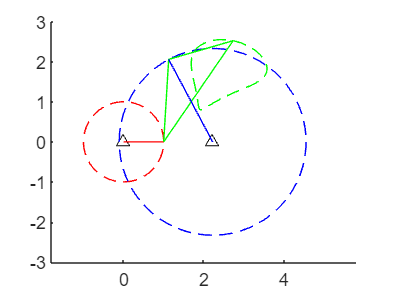


figure()
hold on
plot(O2x,O2y,"^k")
plot(O4x,O4y,"^k")
plot(subs(Ax,0:0.1:2*pi),subs(Ay,0:0.1:2*pi),"--r")
plot(subs(Bx,0:0.1:2*pi),subs(By,0:0.1:2*pi),"--b")
plot(subs(Px,0:0.1:2*pi),subs(Py,0:0.1:2*pi),"--g")

fanimator(h_link2)
fanimator(h_link3)
fanimator(h_link4)
hold off
axis equal

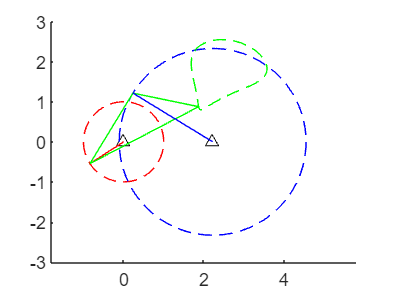

playAnimation